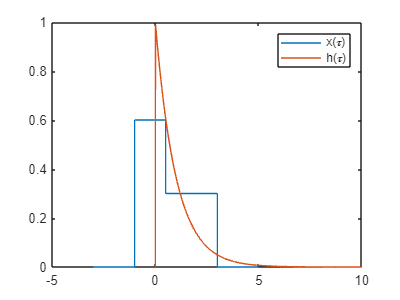

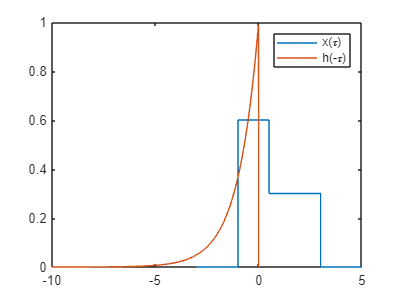

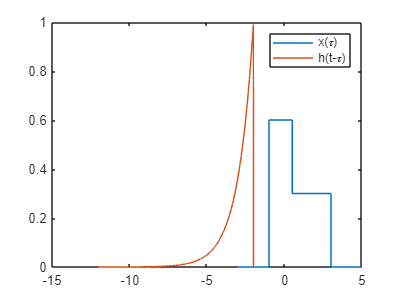

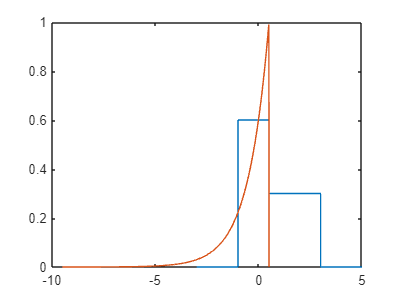

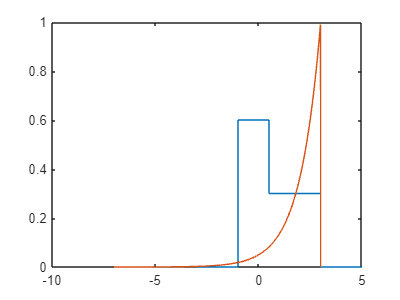

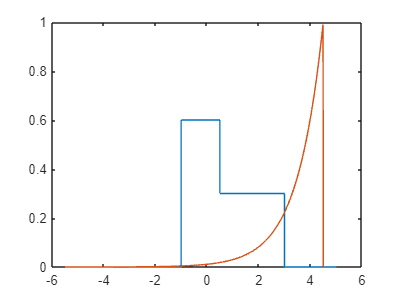

$$ans = \frac{9\,{\mathrm{e}}^{t}}{50}-\frac{9}{50}$$

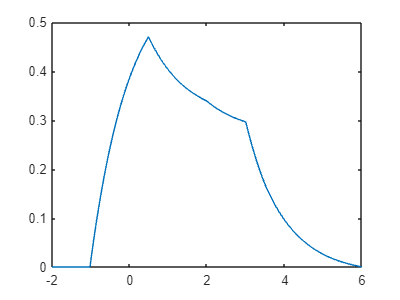

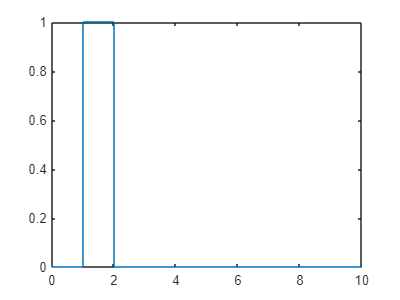

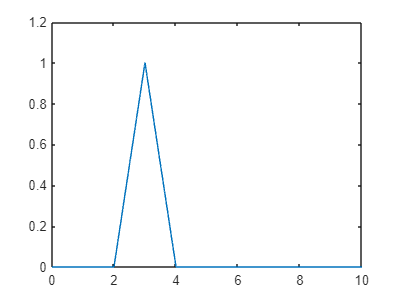

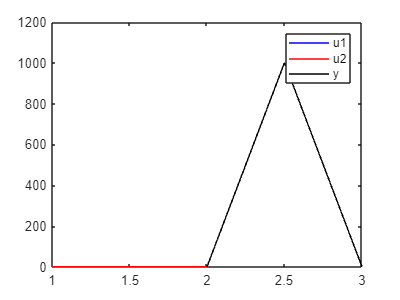

%Sinal de Entrada

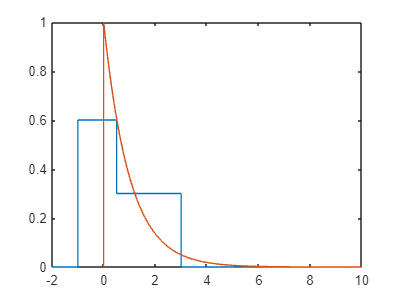

tx0 = -2:0.01:-1;
tx1 = -1:0.01:0.5;
tx2 = 0.5:0.01:3;
tx3 = 3:0.01:10;
x0 = zeros(size(tx0));
x1 = 0.6*ones(size(tx1));
x2 = 0.3*ones(size(tx2));
x3 = zeros(size(tx3));
x = [x0 x1 x2 x3];
tx = [tx0 tx1 tx2 tx3];
figure 
plot(tx, x)
hold on

%Resposta Impulsiva 
th1 = 0:0.01:10;
h1 = exp(-th1);
h = [0 h1];
th = [0 th1];
plot(th, h)
hold off

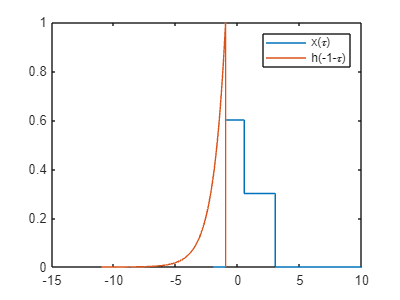


%Sem sobreposicao
t = -1;
figure
plot(tx, x, t - th, h)
legend("x(\tau)", "h(-1-\tau)")

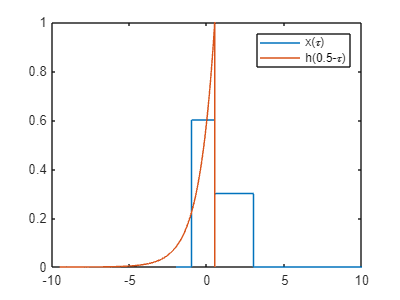


%Sobreposicao parcial
t = 0.5;
figure
plot(tx, x, t - th, h)
legend("x(\tau)", "h(0.5-\tau)")

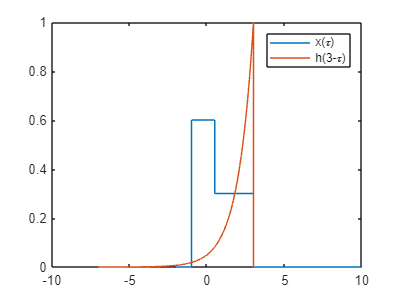


%Sobreposicao total
t = 3;
figure
plot(tx, x, t - th, h)
legend("x(\tau)", "h(3-\tau)")


%Determinando as integrais
syms t r
%Inicio da sobreposicao
f1 = 0.6*exp(-t+r); 
f2 = 0.3*exp(-t+r);
f = int(f1, r, -1, t) 

$$f = \frac{3}{5}-\frac{3\,{\mathrm{e}}^{-t-1}}{5}$$


%Sobreposicao completa
f = int(f1, r, t-0.5, t)

$$f = \frac{3}{5}-\frac{3\,{\mathrm{e}}^{-\frac{1}{2}}}{5}$$

$$f = \frac{3\,{\mathrm{e}}^{3-t}}{10}-\frac{3\,{\mathrm{e}}^{-\frac{1}{2}}}{10}$$

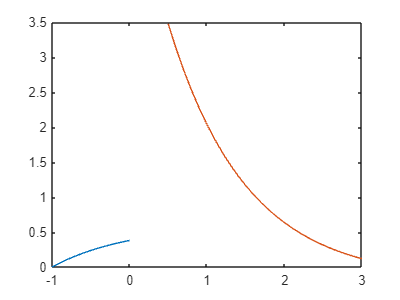


%Sobreposicao estagio saida
f = int(f2, r, t-0.5, 3)

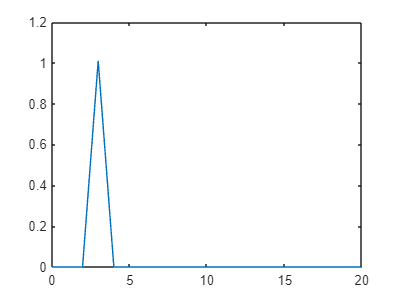

%Exercicio 2
t0 = 0:0.01:1;
t1 = 1:0.01:2;
t2 = 2:0.01:10;
t = [t0 t1 t2];
%Sinal entrada
x0 = zeros(size(t0));
x1 = ones(size(t1));
x2 = zeros(size(t2));
x = [x0 x1 x2];
%Resposta impulsiva
h0 = zeros(size(t0));
h1 = ones(size(t1));
h2 = zeros(size(t2));
h = [h0 h1 h2];

%Convolução 
ys = conv(x, h) * 0.01;
ys(:, [1, 2, 3, 4]) = [];
tys = 0:0.01:20;
plot(tys, ys)